# Neural network based adaptive control of nonlinear uncertain systems

## *Ideal* *case*

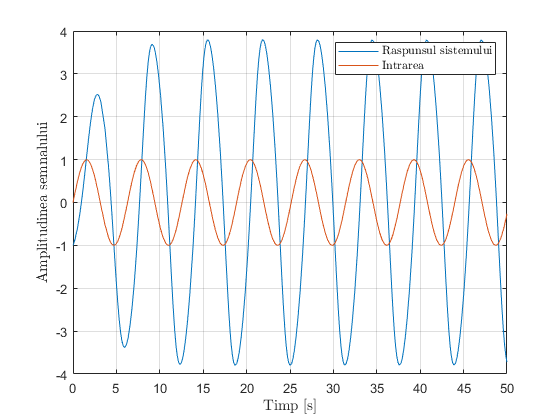

clear; clc;

[t, x] = ode23(@van_der_pol, [0 50], [-1 0.5]);

figure, 
plot(t, x(:, 1)); hold on; grid;
plot(t, sin(t));
xlabel("Timp [s]", "Interpreter","latex");
ylabel("Amplitudinea semnalului", "Interpreter","latex");
legend("Raspunsul sistemului", "Intrarea", "Interpreter", "latex");

## Van der Pol oscilator discrete model simulation

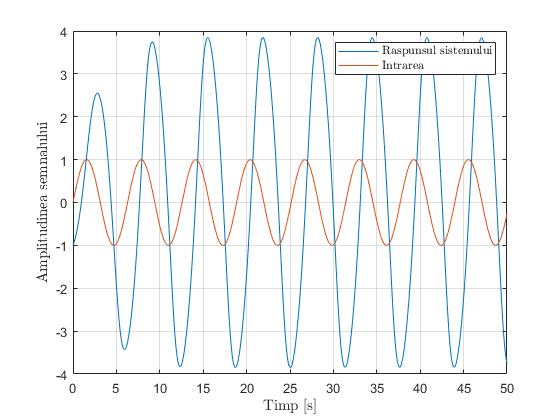

Ts = 0.01;
t = 0:Ts:50;
u = sin(t);
x = zeros(2, length(t));
mu = 0.1;

x0 = [-1; 0.5];
x(:, 1) = x0 + Ts*van_der_pol_derivative(x0, u(1), mu);

for i = 2:length(t)
    x(:, i) = x(:, i - 1) + Ts*van_der_pol_derivative(x(:, i - 1), u(i), mu);
end

figure, 
plot(t, x(1, :)); grid; hold on;
plot(t, u);
xlabel("Timp [s]", "Interpreter","latex");
ylabel("Amplitudinea semnalului", "Interpreter","latex");
legend("Raspunsul sistemului", "Intrarea", "Interpreter", "latex");

## Simulation initialization

**Time interval initialization:**

Ts = 0.05;
t = 0:Ts:50;

**Define the desired trajector using a *****smooth function:***

xd = [sin(0.5*t) + cos(0.25*t); 0.5*cos(0.5*t) - 0.25*sin(0.25*t)];

**Model related initialization:**

mu = 0.1; % model parameter
x0 = [0.5 0.5]'; % initial conditions

**Neural network parameters:**

input_size = 4; % number of inputs
hidden_layer_size = 20; % number of hidden neurons

**Neural network hyperparameters:**

Ac = -eye(2); 
lr = 5; % learning rate
gamma = 0.0001; % damping factor

**Neural network weights initialization:**

Vc = rands(hidden_layer_size, input_size);
Wc = rands(1, hidden_layer_size);

**Simulation initialization:**

x = zeros(2, length(t)); 
x(:, 1) = x0;

e = zeros(2, length(t));
u = zeros(length(t), 1);

changeMoment = ceil(length(t)/2);

## Numeric Simulation

for i = 1:length(t) - 1
    if i == changeMoment
       mu = mu + 2;
    end
    
    % compute current tracking error
    e(:, i) = x(:, i) - xd(:, i);
    
    % neural network input
    x_cnn = [e(:, i); xd(:, i)];
    
    % backpropagation
    dWc = e(:, i)'/Ac*ones(2, 1)*tanh(Vc*x_cnn)';   
    duda = Wc*(eye(hidden_layer_size) - diag(tanh(Vc*x_cnn).^2)); % Wc.*tanh_derivative(Vc*x_cnn)'
    dVc = (e(:, i)'/Ac*ones(2, 1)*duda)'*x_cnn';
    
    Wc = Wc + Ts*(-lr*dWc - gamma*norm(e(:, 1))*Wc);
    Vc = Vc + Ts*(-lr*dVc - gamma*norm(e(:, 1))*Vc);
    
    % inference
    u(i) = -Wc*tanh(Vc*x_cnn);
    
    x(:, i + 1) = x(:, i) + Ts*van_der_pol_derivative(x(:, i), u(i), mu);    
end

## Results visualization

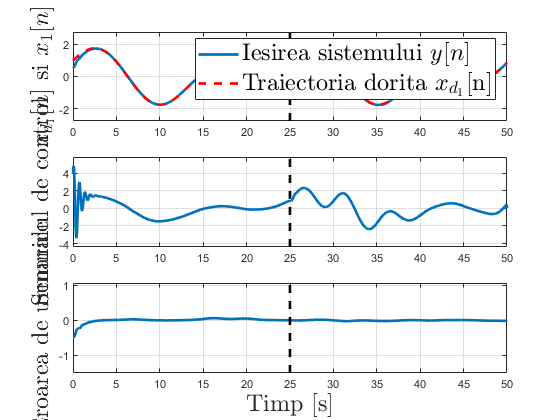

q = -10:Ts:10;
lineWidth = 2;
fontSize = 18;

figure,
subplot(3, 1, 1);
plot(t, x(1, :), "LineWidth", lineWidth); grid; hold on;
plot(t, xd(1, :), '--', "Color", "Red", "LineWidth", lineWidth);
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
axis([0 t(end) min(x(1, :))-1 max(x(1, :))+1])
ylabel("$x_{d_1}[n]$ si $x_{1}[n]$", "Interpreter","latex", "FontSize", fontSize);
legend("Iesirea sistemului $y[n]$", "Traiectoria dorita $x_{d_1}$[n]", ...
    "Interpreter", "Latex", "Location", "northeast", "FontSize", fontSize);

subplot(3, 1, 2);
plot(t, u, "LineWidth", lineWidth); grid; hold on;
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
axis([0 t(end) min(u)-1 max(u) + 1])
ylabel("Semnalul de control", "Interpreter","latex", "FontSize", fontSize);

subplot(3, 1, 3);
plot(t, e(1, :), "LineWidth", lineWidth); grid; hold on;
plot(t(changeMoment)*ones(1, length(q)), q, "--", "Color", "Black", "LineWidth", lineWidth);
axis([0 t(end) min(e(1, :)) - 1 max(e(1, :)) + 1])
ylabel("Eroarea de urmarire", "Interpreter","latex", "FontSize", fontSize);
xlabel("Timp [s]", "Interpreter","latex", "FontSize", fontSize);

function dx = van_der_pol(t, x)
    mu = 0.1;
    u = sin(t);
    
    dx = [x(2);
          mu*(1 - x(1)^2)*x(2) - x(1) + u];
end